# State Estimation of Formation Control Systems

This the final project for course *ET4386 Estimation and Detection*.

clear all;
clc;
close all;

## 1. Data Load

- dt: The time interval

- K: Max iterations

- N: Number of Agents (7)

- M: Number of Edges (12)

- z: Actual positions of each agent (2D position)

- z*: Target positions of each agent

- L: Edge weights ($l_{ij} $: the weight of the edge between positions of the i-th and j-th agent)

- R: The covariance matrix of the noise

load("data.mat");

## 2. Initialization

disp(L); % take a look to the weight

    0.2741   -0.2741   -0.2741    0.1370    0.1370         0         0
   -0.2741    0.6852         0   -0.5482         0         0    0.1370
   -0.2741         0    0.6852         0   -0.5482    0.1370         0
    0.1370   -0.5482         0    0.7537   -0.0685   -0.2741         0
    0.1370         0   -0.5482   -0.0685    0.7537         0   -0.2741
         0         0    0.1370   -0.2741         0    0.2741   -0.1370
         0    0.1370         0         0   -0.2741   -0.1370    0.2741



z_matrix = zeros(7, 2, K); % the matrix containing the positions of all agents for K iterations
z_matrix(:, :, 1) = z;     % initialize the position of the 1-st iteration
k = 1; % current iteration
% u_matrix = zeros(7, 2, K) % control variable matrix

## 3. Control without Noise

The project aims to implement a relative formation control system affected by measurement noise. We will discuss the impact of different estimators and various T noisy measurements on the system.

First, we implement a noise-free relative formation control based on the pseudocode provided in the assignment.

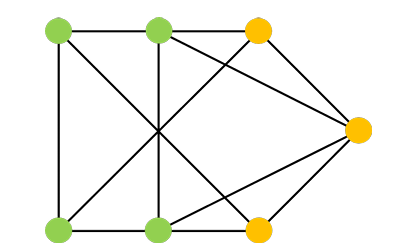

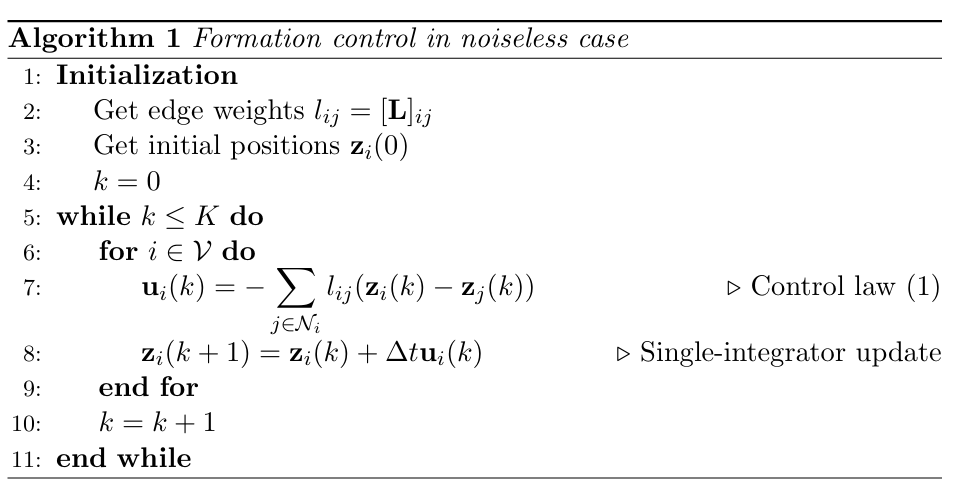

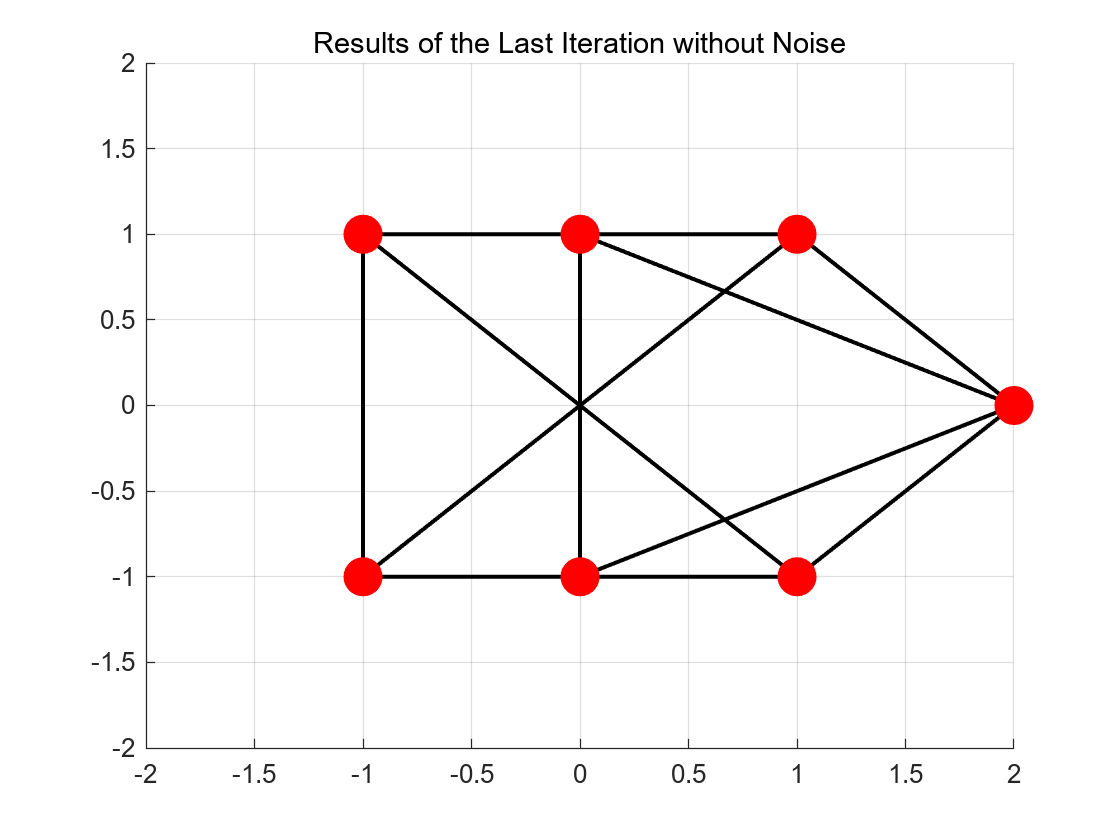

% the hyperparameters used by the reference
% dt = 0.001;
% K = 30000;

dt = 0.1;
K = 4000;

while k <= K
    for i = 1:N
        % iterate to get the new position for agent i at time k
        u_i_k = zeros(1, 2); % initialize the control variable
        z_i_k = z_matrix(i, :, k); % get the old position

        % traverse weight L(i, j) to compute the control variable ui(k)
        for j = 1:N
            u_i_k = u_i_k + L(i, j) * (z_matrix(i, :, k) - z_matrix(j, :, k));
        end

        % for the first three agents, assuming they stay in the target locations from the beginning
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end

        z_i_k_new = z_i_k + dt * u_i_k; % calculate new position using zi(k+1) = zi(k) + dt*ui(k)
        z_matrix(i, :, k+1) = z_i_k_new; % record the new position with z_matrix
    end

    k = k + 1;
end

% calculate the errors
error = compute_error(z_matrix, z_star, K);

% plot the result
plot_formation(z_matrix(:, :, K));
grid on;
title("Results of the Last Iteration without Noise")
saveas(gcf, fullfile('imgs', 'formation_noiseless.png'));

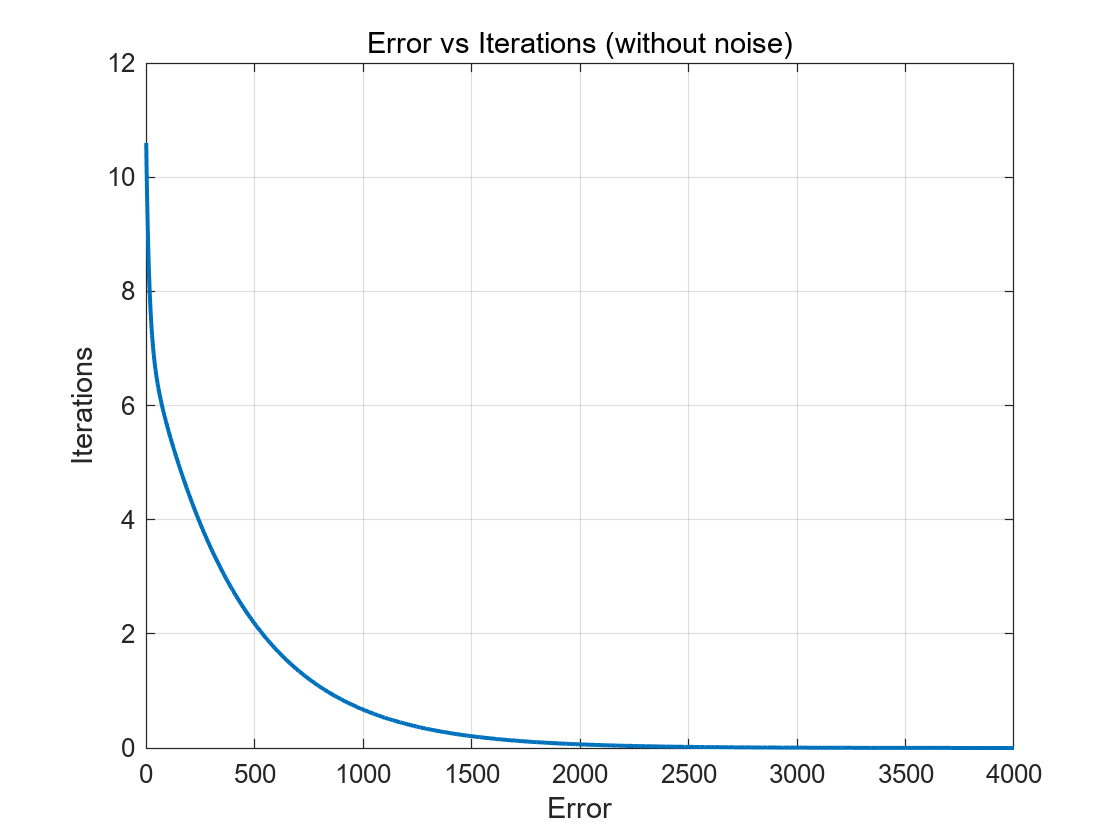

% plot the errors comparing to iterations
figure;
plot(error, 'Linewidth', 1.5); 
xlabel("Error");
ylabel("Iterations");
title("Error vs Iterations (without noise)");
grid on;
saveas(gcf, fullfile('imgs', 'error_noiseless.png'));

## 4. Add Noise and Observation

Next, we simulate the scenario with noise. The noise is added according to covariance matrix R.

The result shows that the noise introduces instability. Overall, there is a convergence trend, but it ultimately fails to converge to the ideal position.

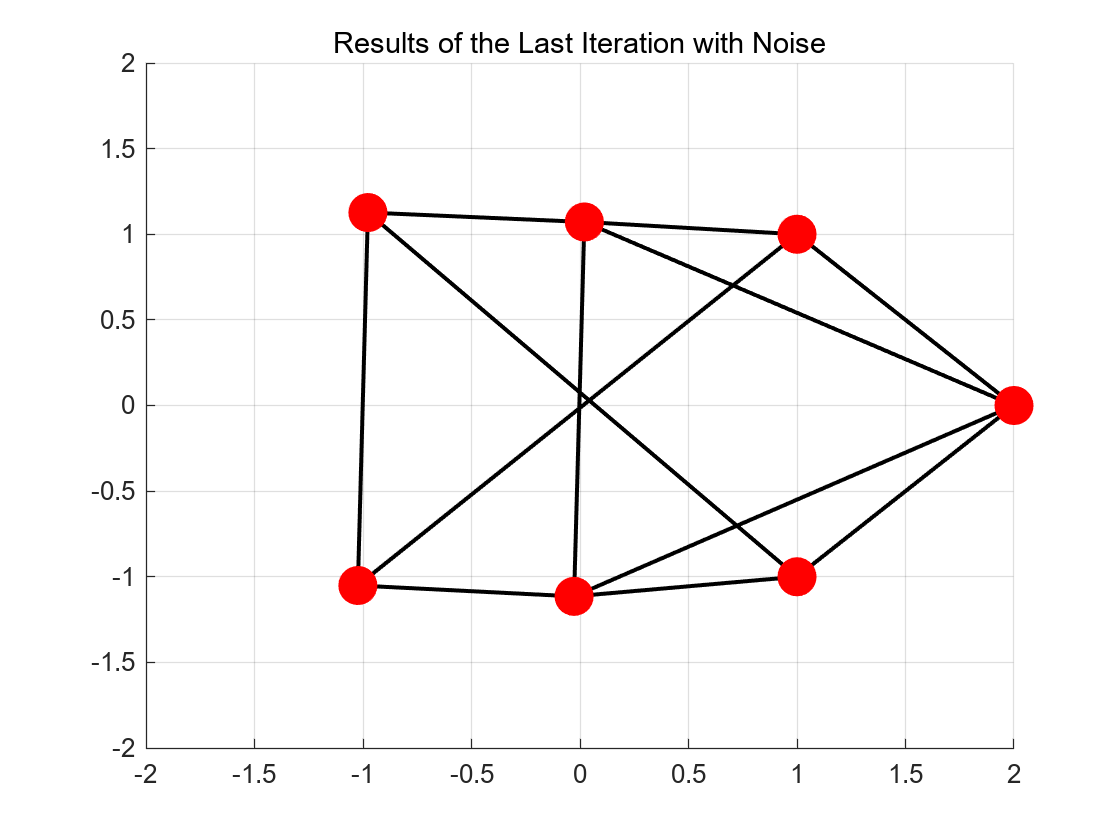

% initialize
z_matrix2 = zeros(7, 2, K);
z_matrix2(:, :, 1) = z;
k = 1;

% retain the observations, i.e. the measurements
% since there are only 12 non-zero edges, only 12 vectors are needed
observations_m = zeros(12, 2, K);

% start iteration
while k <= K
    state_num = 0;

    for i = 1:N
        % iterate to get the new position for agent i at time k
        u_i_k = zeros(1, 2); % initialize the control variable
        z_i_k = z_matrix2(i, :, k);
        
        % traverse weight L(i, j) to compute the control variable ui(k)
        for j = 1:N
            y_k = z_matrix2(i, :, k) - z_matrix2(j, :, k) + mvnrnd([0, 0], R);
            u_i_k = u_i_k + L(i, j) * y_k;

            % x_matrix(i, j, :, k) = x; % problematic, only need to retain where L is non-zero.
            % retain the measurement
            % 1. Only retain measurements where L is non-zero 
            %    and not self-loops
            % 2. Only keep non-zero values in the lower triangular 
            %    matrix of L (since L is a symmetric matrix).
            if (L(i, j) ~= 0 && i < j)
                state_num = state_num + 1;
                observations_m(state_num, :, k) = y_k;
            end
        end
        
        % for the first three agents, assuming they stay in the target locations from the beginning
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end

        z_i_k_new = z_i_k + dt * u_i_k; % calculate new position using zi(k+1) = zi(k) + dt*ui(k)
        z_matrix2(i, :, k+1) = z_i_k_new; % record the new position with z_matrix
    end

    k = k + 1;
end

% calculate the errors
error_no_noise = error;
error = compute_error(z_matrix2, z_star, K);

% plot the trajectories
plot_formation(z_matrix2(:, :, K));
grid on;
title("Results of the Last Iteration with Noise");
saveas(gcf, fullfile('imgs', 'formation_noise.png'));

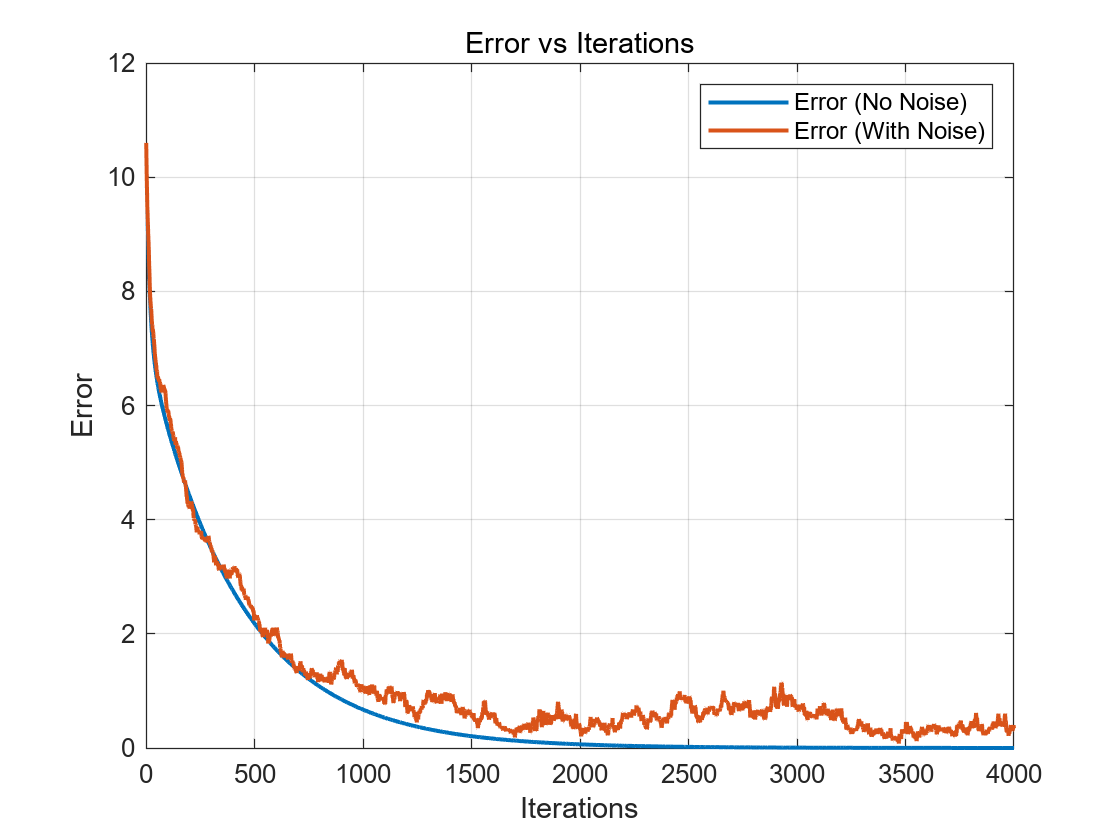

% plot errors compating to iterations
figure;
plot(error_no_noise, "LineWidth", 1.5);
hold on;
plot(error, "LineWidth", 1.5);
xlabel("Iterations");
ylabel("Error");
grid on;
legend('Error (No Noise)', 'Error (With Noise)');
title("Error vs Iterations");
saveas(gcf, fullfile('imgs', 'error_noise_vs_noiseless.png'));

## 5. Applying Different Estimators

In the following section, we will apply different estimators with different number of measurements T, and observe their effects.

% 这里设置估计器的共同参数，用于对比
max_iter = 4000;    % 最大迭代次数
T = 10;             % 每对节点的观测次数 10 100
dt = 0.1;           % 步长

## 5.1 MLE (Unbiased Estimator)

As described in the given reference, MLE equals to MVUE for a linear Gaussian noise case. 

% 初始化参数

z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵
z_matrix_2(:, :, 1) = z;                % 初始状态
vec_T = ones(T, 1);                     % T x 1 全1向量
dimension = 2;                          % 状态维度
I_Dimension = eye(dimension);           % D x D 单位矩阵

% 开始迭代
for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 构造测量值
                vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                H = kron(vec_T, I_Dimension);
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                x_state_m = H * dz_true' + vij_m'; % 带噪声的观测值
                
                % 计算 MLE 解
                Sigma_v = kron(R, eye(T)); % 协方差矩阵
                Sigma_v_inv = inv(Sigma_v); % 逆矩阵
                dz_mle = inv(H' * Sigma_v_inv * H) * H' * Sigma_v_inv * x_state_m; % MLE 解
                
                % 累加输入
                u_i_k = u_i_k + L(i, j) * dz_mle';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new;
    end
end


## 可视化最终结果（MLE）

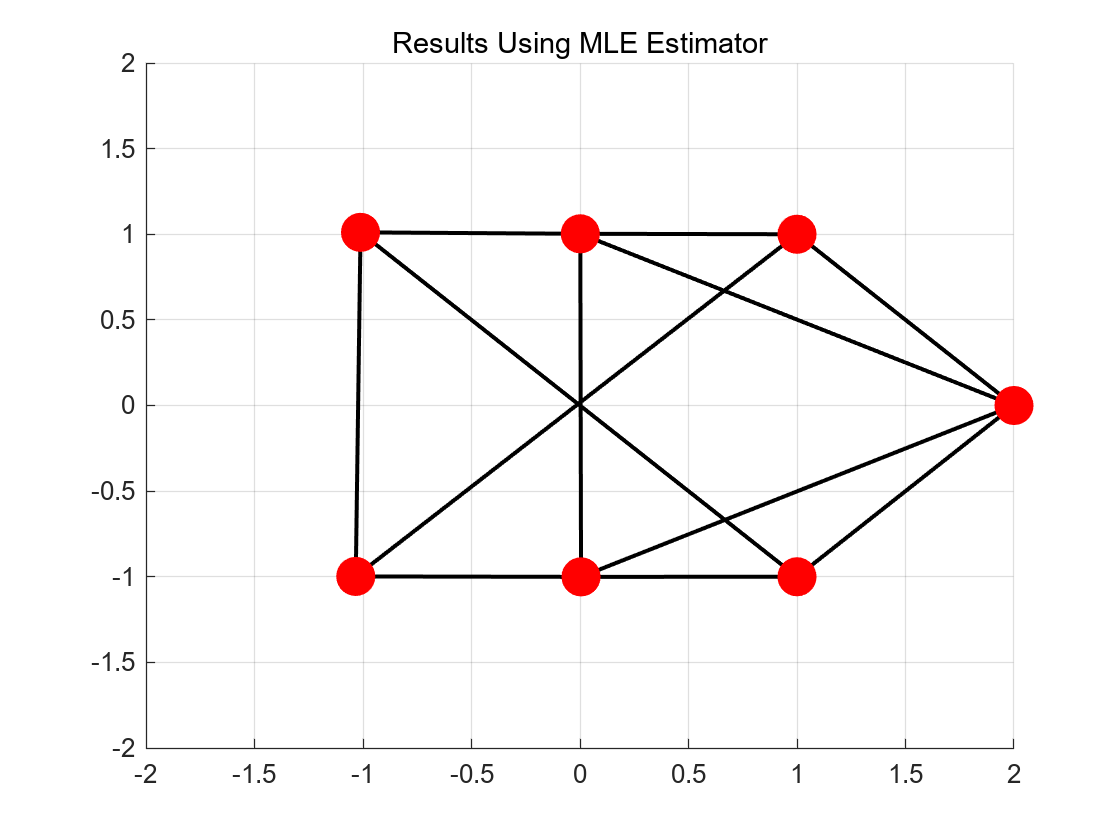


figure;
plot_formation(z_matrix_2(:, :, max_iter)); % 绘制最终状态
grid on;
title("Results Using MLE Estimator");
saveas(gcf, fullfile('imgs', 'formation_mle.png'));

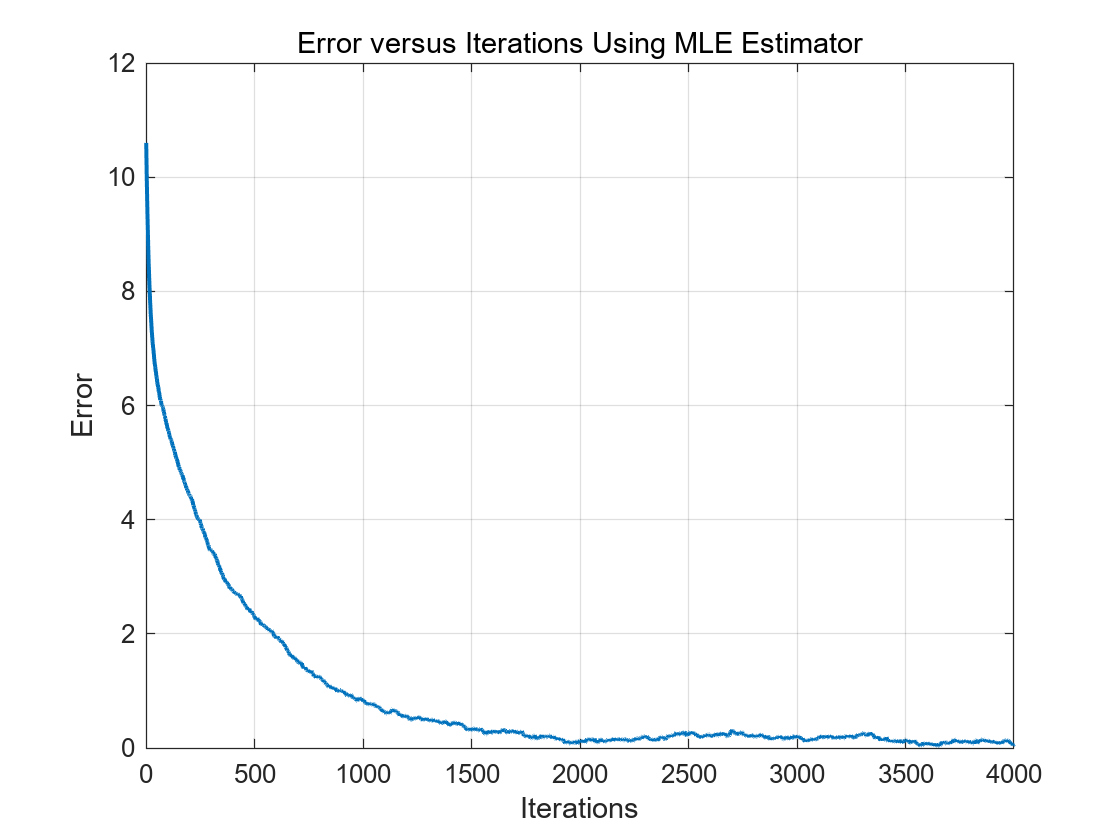

figure;
error_MLE = compute_error(z_matrix_2, z_star, max_iter);
title("Results Using MLE Estimator");
plot(error_MLE, 'LineWidth', 1.5);
xlabel("Iterations");
ylabel("Error");
grid on;
title("Error versus Iterations Using MLE Estimator");
saveas(gcf, fullfile('imgs', 'error_mle.png'));

## 5.2 LSE Estimator

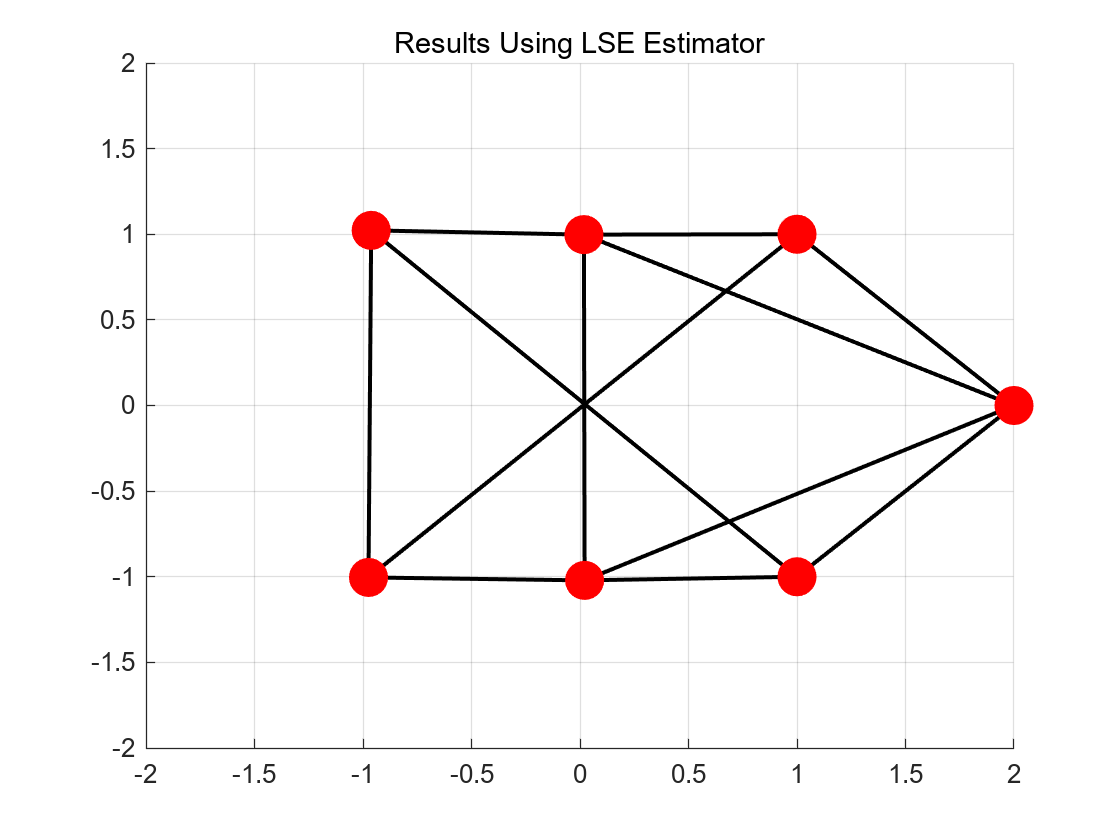

% 5.2 LSE

% 初始化参数
z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵
z_matrix_2(:, :, 1) = z;                % 初始状态
vec_T = ones(T, 1);                     % T x 1 全1向量
dimension = 2;                          % 状态维度
I_Dimension = eye(dimension);           % D x D 单位矩阵

% 开始迭代
for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 构造测量值
                vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                H = kron(vec_T, I_Dimension);
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                x_state_m = H * dz_true' + vij_m'; % 带噪声的观测值
                
                % 计算 LSE 解
                dz_lse =  inv(H' * H) * (H' * x_state_m); % LSE 解

                % 累加输入
                u_i_k = u_i_k + L(i, j) * dz_lse';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new;
    end
end



figure;
plot_formation(z_matrix_2(:, :, max_iter)); 
grid on;
title("Results Using LSE Estimator");
saveas(gcf, fullfile('imgs', 'formation_lse.png'));

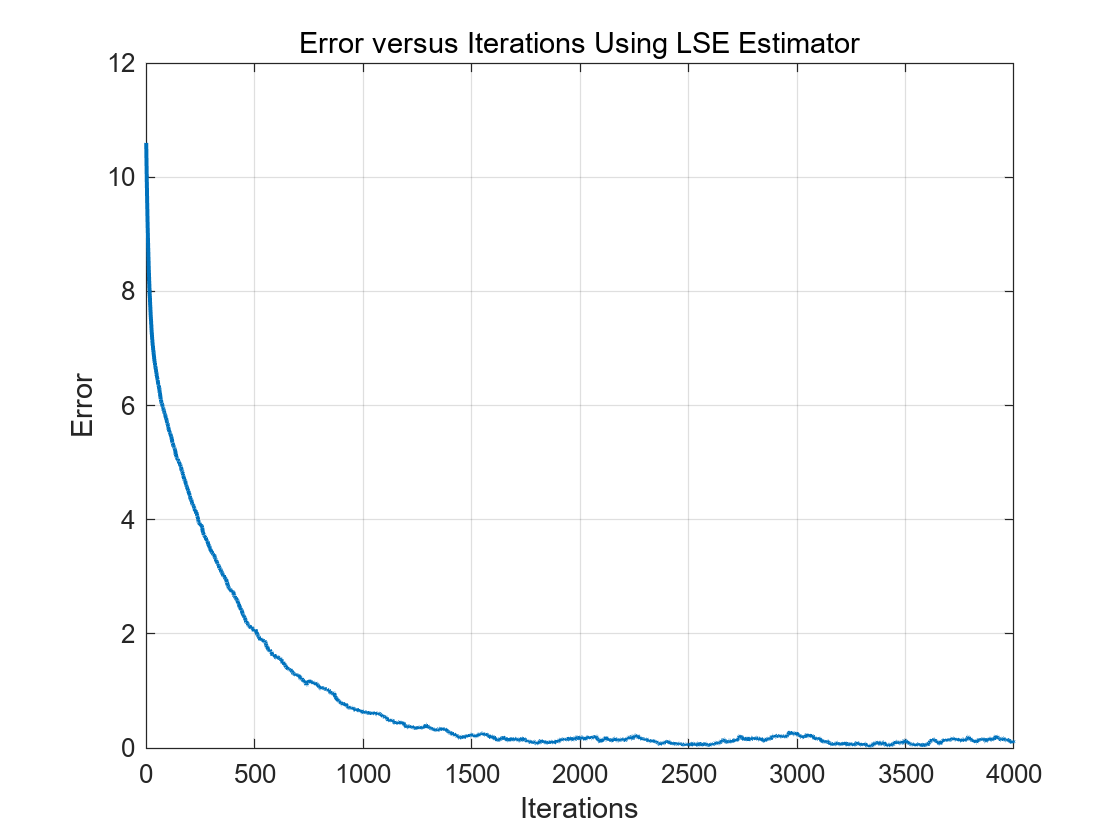

figure;
error_LSE = compute_error(z_matrix_2, z_star, max_iter);
title("Results Using LSE Estimator");
plot(error_LSE, 'LineWidth', 1.5);
xlabel("Iterations");
ylabel("Error");
grid on;
title("Error versus Iterations Using LSE Estimator");
saveas(gcf, fullfile('imgs', 'error_lse.png'));

## 5.3 Wiener Filter

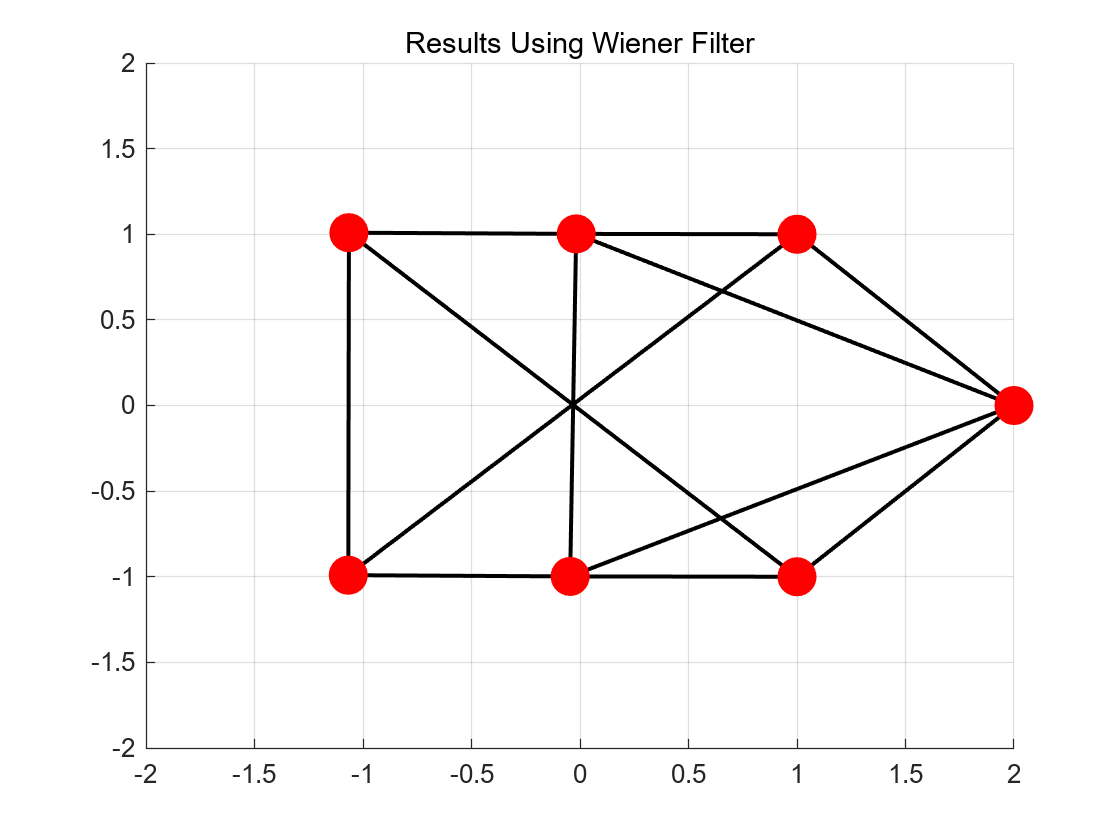

%% 5.3 Wiener估计器
% 初始化参数
z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵 (7个节点，2维，k次迭代)
z_matrix_2(:, :, 1) = z;                % 初始状态
dimension = 2;                          % 状态维度
vec_T = ones(T, 1);                     % T x 1 全1向量
I_Dimension = eye(dimension);           % 2 x 2 单位矩阵
R_extended = kron(eye(T), R);           % 噪声协方差矩阵

% 迭代过程
for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 生成带噪声的观测值
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k); % 相对状态 (1x2)
                vij_m = mvnrnd(zeros(1, T * dimension), R_extended);          % 噪声
                H = kron(vec_T, I_Dimension);                       % T*2 x 2 测量矩阵
                x_state_m = H * dz_true' + vij_m';                  % 带噪声测量值 (T*2 x 1)
                
                % 动态计算维纳滤波器的协方差矩阵
                R_ss = dz_true' * dz_true;                          % 真实信号的自相关矩阵 (2x2)
                R_xx = H * R_ss * H' + R_extended;                           % 观测信号的协方差矩阵 (T*2 x T*2)
                C_theta_x = R_ss * H';                              % 信号和观测值的协方差矩阵 (2xT*2)
                
                % 动态计算维纳滤波器权重矩阵 W
                W = C_theta_x / R_xx;                               % 维纳滤波器权重矩阵 (2xT*2)
                
                % 使用维纳滤波器估计 dz
                dz_estimate = W * x_state_m;                        % 维纳滤波器的估计结果 (2x1)
                
                % 累加输入
                u_i_k = u_i_k + L(i, j) * dz_estimate';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0; % 固定节点的输入为0
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new; % 保存更新后的状态
    end
end

% 可视化最终结果
figure;
plot_formation(z_matrix_2(:, :, max_iter)); % 自定义绘图函数
grid on;
title("Results Using Wiener Filter");
saveas(gcf, fullfile('imgs', 'formation_wiener.png'));

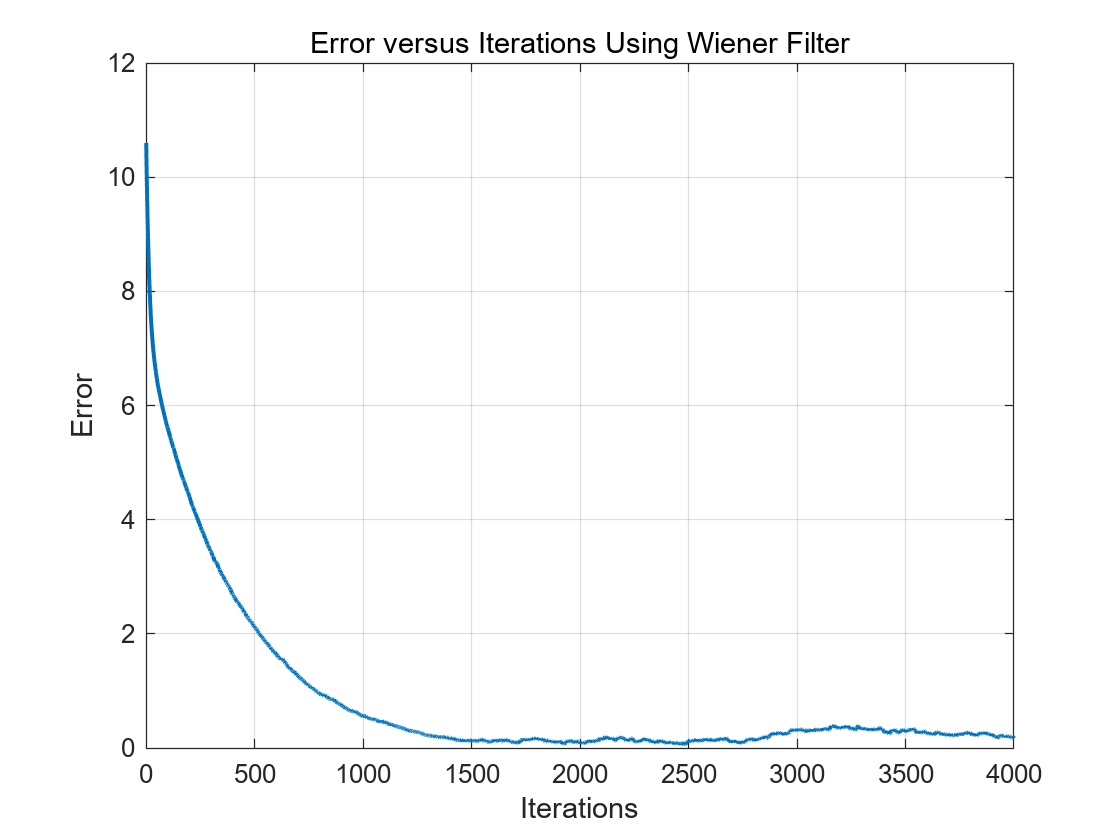


error_Wiener = compute_error(z_matrix_2, z_star, max_iter);
figure;
plot(error_Wiener, 'LineWidth', 1.5);
xlabel("Iterations");
ylabel("Error");
grid on;
title("Error versus Iterations Using Wiener Filter");
saveas(gcf, fullfile('imgs', 'error_wiener.png'));

## 6. Comparison of Different Estimators

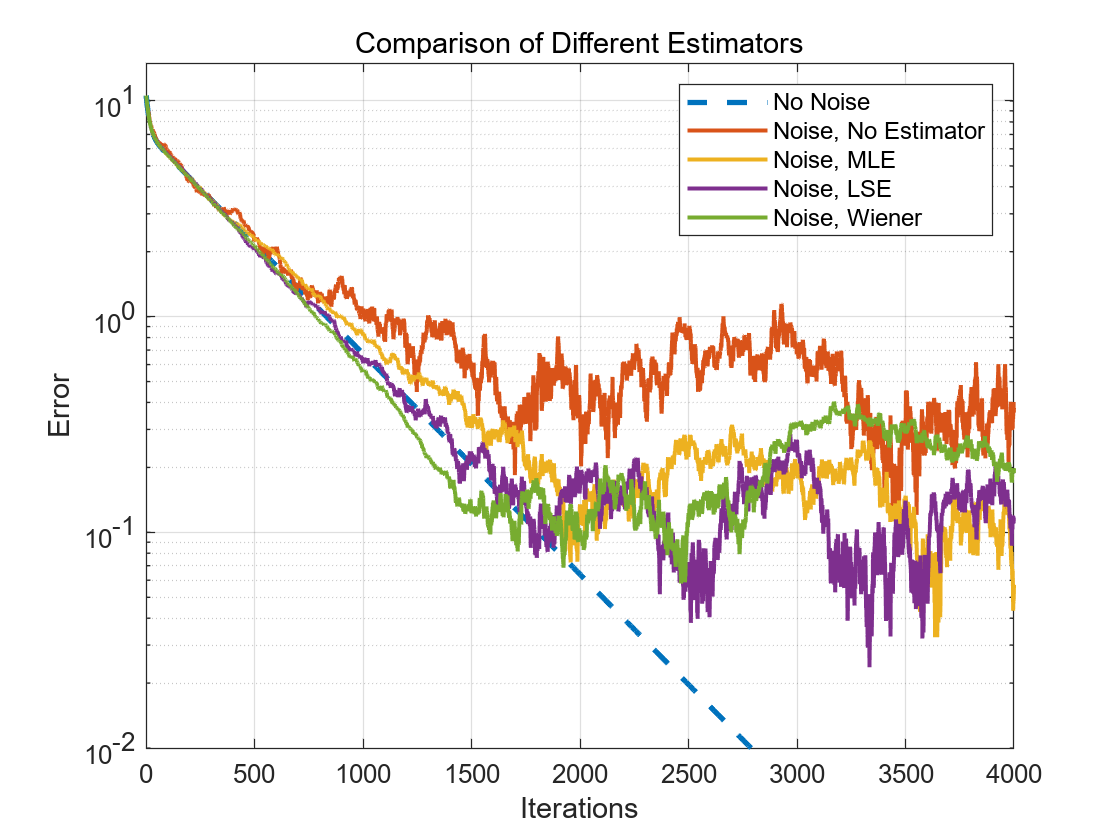

figure;
plot(error_no_noise, '--', 'LineWidth', 2);
hold on;
plot(error, 'LineWidth', 1.5);
hold on;
plot(error_MLE, 'LineWidth', 1.5);
hold on;
plot(error_LSE, 'LineWidth', 1.5);
hold on;
plot(error_Wiener, 'LineWidth', 1.5);
hold on;

grid on;
xlabel("Iterations");
ylabel("Error");
set(gca, 'YScale', 'log');
ylim([1e-2, 1.5e1]);
title("Comparison of Different Estimators");
legend('No Noise', 'Noise, No Estimator', 'Noise, MLE', 'Noise, LSE', 'Noise, Wiener');
saveas(gcf, fullfile('imgs', 'error_mle_lse_wiener.png'));

## 7. Comparison of Estimators with Different T

T_values = [5, 10, 20, 50]; % T values for Testing

### 7.1 MLE

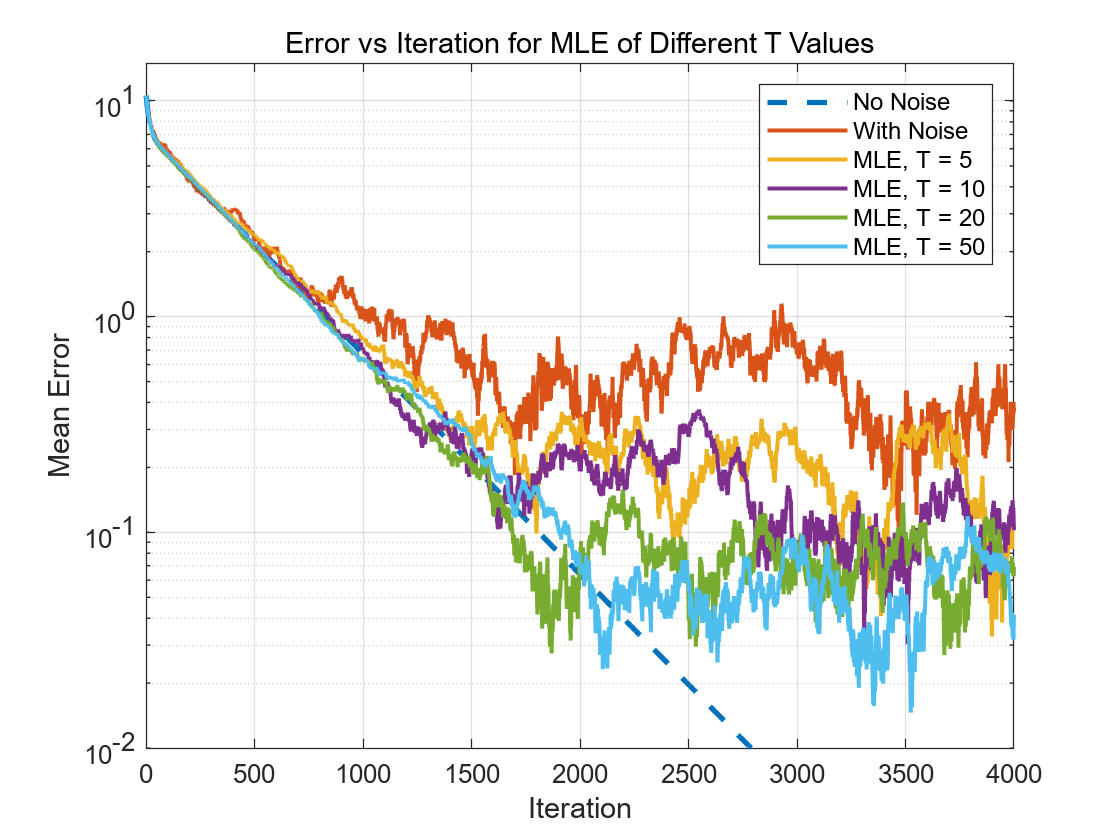

errors_different_T_lse = zeros(max_iter, length(T_values)); % Errors of different T

for t_idx = 1:length(T_values)
    T = T_values(t_idx); % Current T
    vec_T = ones(T, 1);  % T x 1 one-vector
    z_matrix_2 = zeros(7, 2, max_iter + 1); % state-matrix
    z_matrix_2(:, :, 1) = z; % Initial state

    % Initial iteration
    for k = 1:max_iter
        for i = 1:N
            % initial input
            u_i_k = zeros(1, dimension);

            % neighbors
            for j = 1:N
                if L(i, j) ~= 0 && i ~= j
                    vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                    H = kron(vec_T, I_Dimension);
                    dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                    x_state_m = H * dz_true' + vij_m'; % noisy observations

                    % 计算 MLE 解
                    Sigma_v = kron(R, eye(T)); % 协方差矩阵
                    Sigma_v_inv = inv(Sigma_v); % 逆矩阵
                    dz_mle = inv(H' * Sigma_v_inv * H) * H' * Sigma_v_inv * x_state_m; % MLE 解

                    % 累加输入
                    u_i_k = u_i_k + L(i, j) * dz_mle';
                end
            end

            % 更新状态（固定节点不更新）
            if i == 1 || i == 2 || i == 3
                u_i_k = 0;
            end
            z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
            z_matrix_2(i, :, k + 1) = z_i_k_new;
        end
    end

    % 计算误差
    errors_different_T_lse(:, t_idx) = compute_error(z_matrix_2, z_star, max_iter);
end

% 绘制误差随迭代次数变化的图
figure;
plot(error_no_noise, '--', 'LineWidth', 2, 'DisplayName', 'No Noise');
hold on;
plot(error, 'LineWidth', 1.5, 'DisplayName', 'With Noise');
hold on; 
for t_idx = 1:length(T_values)
    plot(errors_different_T_lse(:, t_idx), 'LineWidth', 1.5, 'DisplayName', ['MLE, T = ' num2str(T_values(t_idx))]);
    hold on;
end

legend('show');
xlabel('Iteration');
ylabel('Mean Error');
set(gca, 'YScale', 'log');
ylim([1e-2, 1.5e1]);
title('Error vs Iteration for MLE of Different T Values');
grid on;

% 保存图片
saveas(gcf, fullfile('imgs', 'error_different_T_mle.png'));

### 7.2 LSE

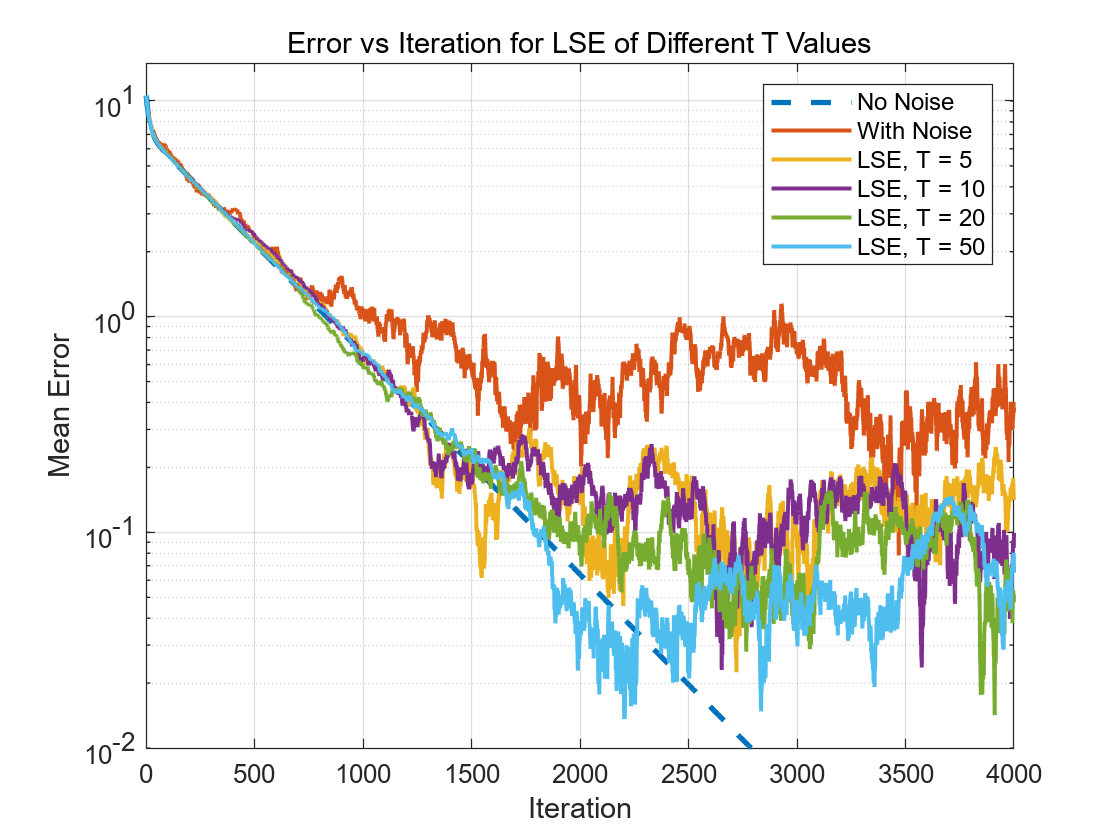

errors_different_T_lse = zeros(max_iter, length(T_values)); % 保存误差

for t_idx = 1:length(T_values)
    T = T_values(t_idx); % 当前 T 值
    vec_T = ones(T, 1);  % T x 1 全1向量
    z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵
    z_matrix_2(:, :, 1) = z; % 初始状态

    % 开始迭代
    for k = 1:max_iter
        for i = 1:N
            % 初始化输入
            u_i_k = zeros(1, dimension);

            % 遍历邻居节点
            for j = 1:N
                if L(i, j) ~= 0 && i ~= j
                    % 构造测量值
                    vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                    H = kron(vec_T, I_Dimension);
                    dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                    x_state_m = H * dz_true' + vij_m'; % 带噪声的观测值
                
                    % 计算 LSE 解
                    dz_lse =  inv(H' * H) * (H' * x_state_m); % LSE 解

                    % 累加输入
                    u_i_k = u_i_k + L(i, j) * dz_lse';
                end
            end

            % 更新状态（固定节点不更新）
            if i == 1 || i == 2 || i == 3
                u_i_k = 0;
            end
            z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
            z_matrix_2(i, :, k + 1) = z_i_k_new;
        end
    end

    % 计算误差
    errors_different_T_lse(:, t_idx) = compute_error(z_matrix_2, z_star, max_iter);
end

% 绘制误差随迭代次数变化的图
figure;
plot(error_no_noise, '--', 'LineWidth', 2, 'DisplayName', 'No Noise');
hold on;
plot(error, 'LineWidth', 1.5, 'DisplayName', 'With Noise');
hold on; 
for t_idx = 1:length(T_values)
    plot(errors_different_T_lse(:, t_idx), 'LineWidth', 1.5, 'DisplayName', ['LSE, T = ' num2str(T_values(t_idx))]);
    hold on;
end

legend('show');
xlabel('Iteration');
ylabel('Mean Error');
set(gca, 'YScale', 'log');
ylim([1e-2, 1.5e1]);
title('Error vs Iteration for LSE of Different T Values');
grid on;

% 保存图片
saveas(gcf, fullfile('imgs', 'error_different_T_lse.png'));

### 7.3 Wiener

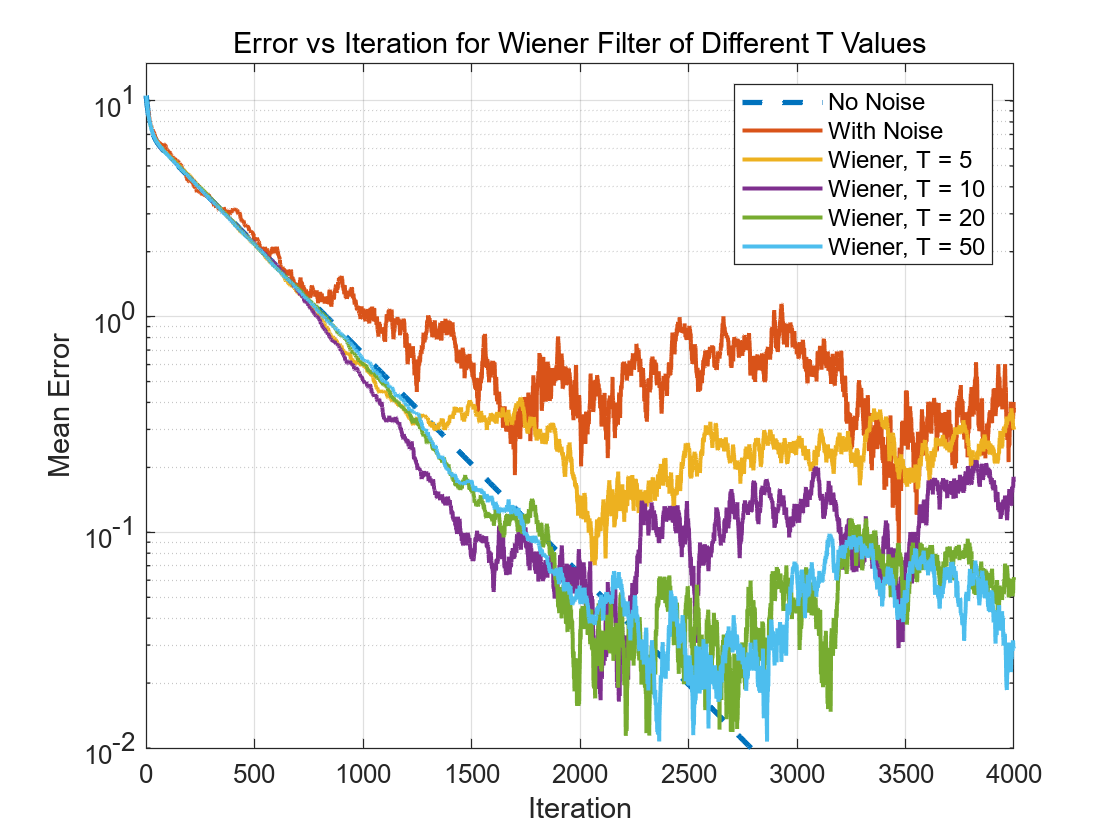

errors_different_T_Wiener = zeros(max_iter, length(T_values)); % 保存误差

for t_idx = 1:length(T_values)
    T = T_values(t_idx); % 当前 T 值
    R_extended = kron(eye(T), R);           % 噪声协方差矩阵
    vec_T = ones(T, 1);  % T x 1 全1向量
    z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵
    z_matrix_2(:, :, 1) = z; % 初始状态

    % 开始迭代
    for k = 1:max_iter
        for i = 1:N
            % 初始化输入
            u_i_k = zeros(1, dimension);

            % 遍历邻居节点
            for j = 1:N
                if L(i, j) ~= 0 && i ~= j
                    dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k); % 相对状态 (1x2)
                    vij_m = mvnrnd(zeros(1, T * dimension), R_extended);          % 噪声
                    H = kron(vec_T, I_Dimension);                       % T*2 x 2 测量矩阵
                    x_state_m = H * dz_true' + vij_m';                  % 带噪声测量值 (T*2 x 1)
                
                    % 动态计算维纳滤波器的协方差矩阵
                    R_ss = dz_true' * dz_true;                          % 真实信号的自相关矩阵 (2x2)
                    R_xx = H * R_ss * H' + R_extended;                           % 观测信号的协方差矩阵 (T*2 x T*2)
                    C_theta_x = R_ss * H';                              % 信号和观测值的协方差矩阵 (2xT*2)
                
                    % 动态计算维纳滤波器权重矩阵 W
                    W = C_theta_x / R_xx;                               % 维纳滤波器权重矩阵 (2xT*2)
                
                    % 使用维纳滤波器估计 dz
                    dz_estimate = W * x_state_m;                        % 维纳滤波器的估计结果 (2x1)
                
                    % 累加输入
                    u_i_k = u_i_k + L(i, j) * dz_estimate';
                end
            end

            % 更新状态（固定节点不更新）
            if i == 1 || i == 2 || i == 3
                u_i_k = 0;
            end
            z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
            z_matrix_2(i, :, k + 1) = z_i_k_new;
        end
    end

    % 计算误差
    errors_different_T_Wiener(:, t_idx) = compute_error(z_matrix_2, z_star, max_iter);
end

% 绘制误差随迭代次数变化的图
figure;
plot(error_no_noise, '--', 'LineWidth', 2, 'DisplayName', 'No Noise');
hold on;
plot(error, 'LineWidth', 1.5, 'DisplayName', 'With Noise');
hold on; 
for t_idx = 1:length(T_values)
    plot(errors_different_T_Wiener(:, t_idx), 'LineWidth', 1.5, 'DisplayName', ['Wiener, T = ' num2str(T_values(t_idx))]);
    hold on;
end

legend('show');
xlabel('Iteration');
ylabel('Mean Error');
set(gca, 'YScale', 'log');
ylim([1e-2, 1.5e1]);
title('Error vs Iteration for Wiener Filter of Different T Values');
grid on;

% 保存图片
saveas(gcf, fullfile('imgs', 'error_different_T_wiener.png'));